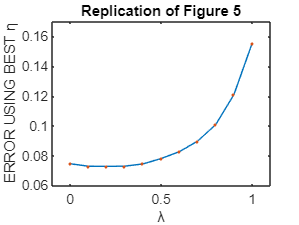

Wexact=([0:6]/6)';
Winitial=[0 0.5 0.5 0.5 0.5 0.5 1]';
lamlist=[0:0.1:1];
alist=[0.3 0.3 0.3 0.25 0.25 0.25 0.2 0.2 0.15 0.1 0.05];
store=zeros(11,13);
X=diag(ones(1,7));
% Update after sequence
tol=0.1;
for chooselam=1:11
    lam=lamlist(chooselam);
    a=alist(chooselam);
for choosea=1:1
    

for set=1:100
    Wold=Winitial;
    Wnew=Wold;
      for i=1:10
         z=zeros(5,1);
         episode=training_sets(i,:,set);
         for j=1:length(episode)
             z=lam*z+X(2:6,episode(j));
             TD=Wold'*( X(:,episode(j+1))-X(:,episode(j)) ); % might be different
             Wnew(2:6)=Wnew(2:6)+0.75*a*TD*z;
             if episode(j+1)>=6.5
                 break
             elseif episode(j+1)<=1.5
                 break
             end
         end
         Wold=Wnew;
      end
RMS(set)=sqrt(mean((Wnew-Wexact).^2));
end
store(chooselam,choosea)=mean(RMS);

end

end
plot(lamlist,store(:,1))
hold on
plot(lamlist,store(:,1),'.')
title('Replication of Figure 5')
xlim([-0.1,1.1])
ylim([0.06,0.17])
xlabel('λ')
ylabel('ERROR USING BEST η')